## Assignment 02

clear all;
close all;
clc;

format short;

### 0. Introduction

We know that the distribution is an hyper-exponential one. From that we know that the moments are equal to:


$$E[X] = \frac{p_1}{\lambda_1} + \frac{1-p_1}{\lambda_2}$$



$$E[X^2] = 2 \left( \frac{p_1}{\lambda_1^2} + \frac{1-p_1}{\lambda_2^2} \right)$$



$$E[X^3] = 6 \left( \frac{p_1}{\lambda_1^3} + \frac{1-p_1}{\lambda_2^3} \right)$$


From this we can easily apply the *method of moments.*

Moreover the PDF function is:


$$f(t) = p_1 \lambda_1e^{-\lambda_1 t} + (1-p_1)\lambda_2 e^{-\lambda_2 t}$$


And the CDF function is:


$$F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$$


### 1. Load data

T = readtable('data.xlsx');
T.Properties.VariableNames = {'data'};
data = T.data

data =   143.3766
  515.9312
  741.3055
  127.2085
  452.0866
  408.2421
  734.4828
  297.0595
  610.7683
  171.3931


N = height(T)

N = 80

### 2. Compute stats

#### 2.1 Moments

First moment

x_1 = (1/N)*sum(data)

x_1 = 133.0848

Second moment

x_2 = (1/N)*sum(data.^2)

x_2 = 4.7312e+04

Third moment

x_3 = (1/N)*sum(data.^3)

x_3 = 2.4217e+07

Fourth moment

x_4 = (1/N)*sum(data.^4)

x_4 = 1.4274e+10

#### 2.2 Compute $\sigma^2$, $\sigma$ and $C_v$

Mean (used for the $C_v$ computation)

mu = mean(data)

mu = 133.0848

Variance

sigma_2_unbiased = var(data)

sigma_2_unbiased = 2.9975e+04

sigma_2 = x_2 - x_1^2

sigma_2 = 2.9600e+04

Standard deviation

sigma_unbiased = sqrt(sigma_2_unbiased)

sigma_unbiased = 173.1333

sigma = sqrt(sigma_2)

sigma = 172.0478

Coefficient of variation

cv = sigma / mu

cv = 1.2928

#### 2.3 Skewness $\gamma$

The skewness is defined as:


$$\gamma = E \left[ \left( \frac{X-\mu}{\sigma} \right)^3 \right] =
\frac{E[X^3] - 2\mu\sigma^2 - \mu^3}{\sigma^3}$$


gamma = (x_3 - 2*mu*sigma_2 - mu^3) ./ (sigma^3)

gamma = 2.7454

gamma_unbiased = skewness(data)

gamma_unbiased = 1.9719

#### 2.4 Kurtois $\beta$


$$\beta= E \left[ \left( \frac{X-\mu}{\sigma} \right)^4 \right] - 3=
\frac{E[(X - \mu)^4]}{\sigma^4} - 3$$


beta = ((1/N) * sum((data - mu).^4)) ./ (sigma^4) - 3

beta = 3.2421

%beta_unbiased = kurtosis(data) - 3

### 3. Fitting

#### 3.1 Maximum Likelihood method

First we have to compute the likelihood function. So, first let's hyphotesize some valure for $\lambda_1, \lambda_2$ and $p_1$.


$$\lambda_1=0.001$$



$$\lambda_2=0.001$$



$$p_1=0.5$$


l1 = 0.001;
l2 = 0.001;
p1 = 0.5;

So, we have to compute $log(f(t))$

log_pdf = @(data,p1,l1,l2) log10(p1*l1*exp(-l1*data) + (1-p1)*l2*exp(-l2*data));
lpdf = log_pdf(data,p1,l1,l2)

lpdf =    -3.0623
   -3.2241
   -3.3219
   -3.0552
   -3.1963
   -3.1773
   -3.3190
   -3.1290
   -3.2653
   -3.0744


log_likehood = sum(lpdf)

log_likehood = -244.6238

Let's now pass to the maximization procedure:

params = mle(data,'logpdf',log_pdf,'start',[p1,l1,l2], 'Lowerbound', [0, 0, 0], 'Upperbound', [1, 0.1, 0.1])

params =     0.4525    0.0043    0.0202


Let's evaluate the fit:

p1_ml = params(1)

p1_ml = 0.4525

l1_ml = params(2)

l1_ml = 0.0043

l2_ml = params(3)

l2_ml = 0.0202

fitted_log_likelihood = sum(log_pdf(data,p1_ml,l1_ml,l2_ml))

fitted_log_likelihood = -202.0410

Approximating CDF:

sorted_data = sort(data)

sorted_data =     0.4034
    0.7568
    1.4335
    2.6746
    3.3140
    4.9987
    7.0688
    7.1954
    8.6078
    9.1509


t = 1/80:1/80:1

t =     0.0125    0.0250    0.0375    0.0500    0.0625    0.0750    0.0875    0.1000    0.1125    0.1250    0.1375    0.1500    0.1625    0.1750    0.1875    0.2000    0.2125    0.2250    0.2375    0.2500    0.2625    0.2750    0.2875    0.3000    0.3125    0.3250    0.3375    0.3500    0.3625    0.3750    0.3875    0.4000    0.4125    0.4250    0.4375    0.4500    0.4625    0.4750    0.4875    0.5000    0.5125    0.5250    0.5375    0.5500    0.5625    0.5750    0.5875    0.6000    0.6125    0.6250


figure();
plot(sorted_data, t, 'LineWidth', 2);
grid on;
hold on;

Let's now compare it with the analytical $F(t) = 1-p_1e^{-\lambda_1 t} - (1-p_1)e^{-\lambda_2 t}$:

F = @(t) 1 - p1_ml*exp(-l1_ml*t) - (1-p1_ml)*exp(-l2_ml*t);
cdf_data_ml = F(sorted_data)

cdf_data_ml =     0.0052
    0.0098
    0.0184
    0.0339
    0.0418
    0.0621
    0.0863
    0.0877
    0.1037
    0.1097


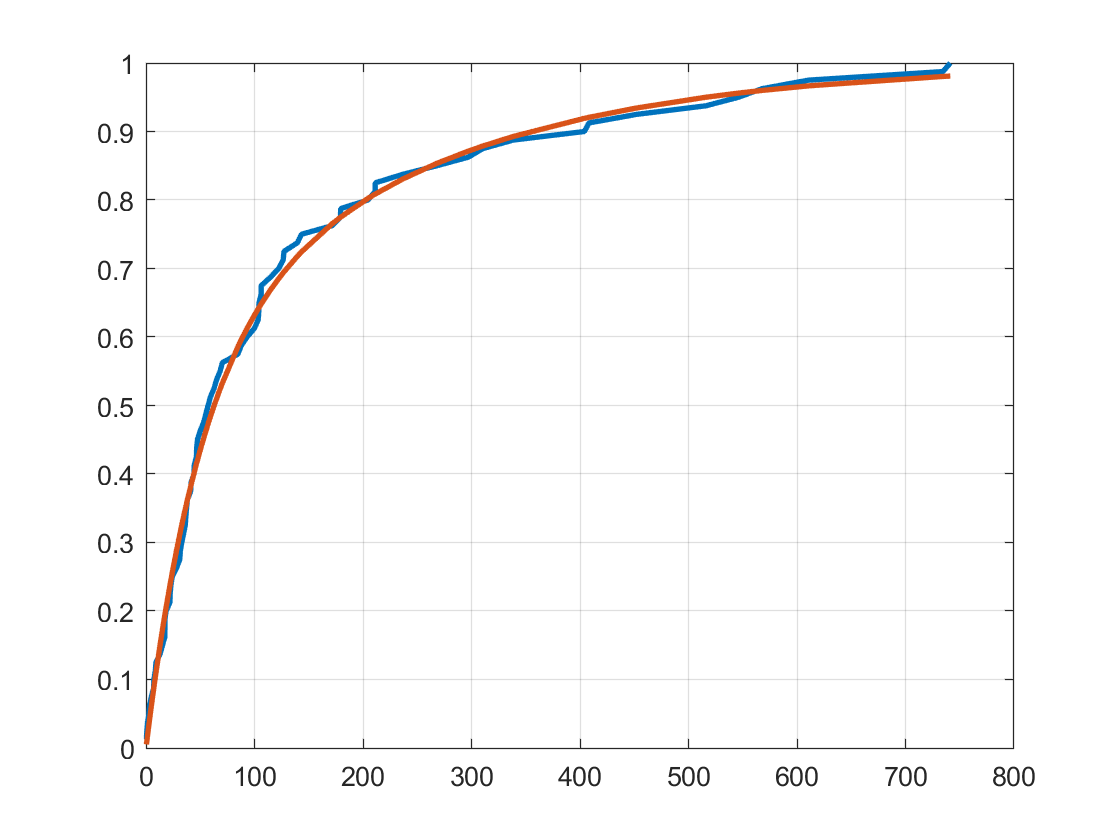

plot(sorted_data, cdf_data_ml, 'LineWidth', 2);
hold off;

#### 3.2 Method of moments

Recalling the moments of an hyper-exponential distribution:


$$E[X] = \frac{p_1}{\lambda_1} + \frac{1-p_1}{\lambda_2}$$



$$E[X^2] = 2 \left( \frac{p_1}{\lambda_1^2} + \frac{1-p_1}{\lambda_2^2} \right)$$



$$E[X^3] = 6 \left( \frac{p_1}{\lambda_1^3} + \frac{1-p_1}{\lambda_2^3} \right)$$


x_1

x_1 = 133.0848

x_2

x_2 = 4.7312e+04

x_3

x_3 = 2.4217e+07

So, we have to solve the system of 3 equations in 3 unknowns:

F = @(x) [x(1)/x(2) + (1-x(1))/x(3) - x_1;
          2*(x(1)/(x(2)^2) + (1-x(1))/(x(3)^2)) - x_2;
          6*(x(1)/(x(2)^3) + (1-x(1))/(x(3)^3)) - x_3];

x0 = [0.5;0.001;0.001];
options = optimoptions('fsolve','Display','iter','FunctionTolerance',1e-18);
[x,fval] = fsolve(F,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          4       3.571e+19                      5.38e+22               1
     1          8     6.32349e+18    0.000469516       7.19e+21               1
     2         12     1.11208e+18    0.000621934       9.63e+20               1
     3         16     1.92398e+17    0.000816485        1.3e+20               1
     4         20     3.20097e+16     0.00104946       1.76e+19               1
     5         24     4.84702e+15     0.00128349       2.45e+18               1
     6         28     5.82702e+14     0.00139856       3.51e+17               1
     7         32     3.91328e+13     0.00117372       4.92e+16               1
     8         36     5.89224e+11    0.000562987       4.63e+15               1
     9         40     2.50311e+08    9.00213e-05       8.95e+13               1
    10         44     1.14829e+07    1.8877

x =     0.5000
    0.0063
    0.0063


fval = 	1.0e+03 *

    0.0261
    3.3885
   -0.0047


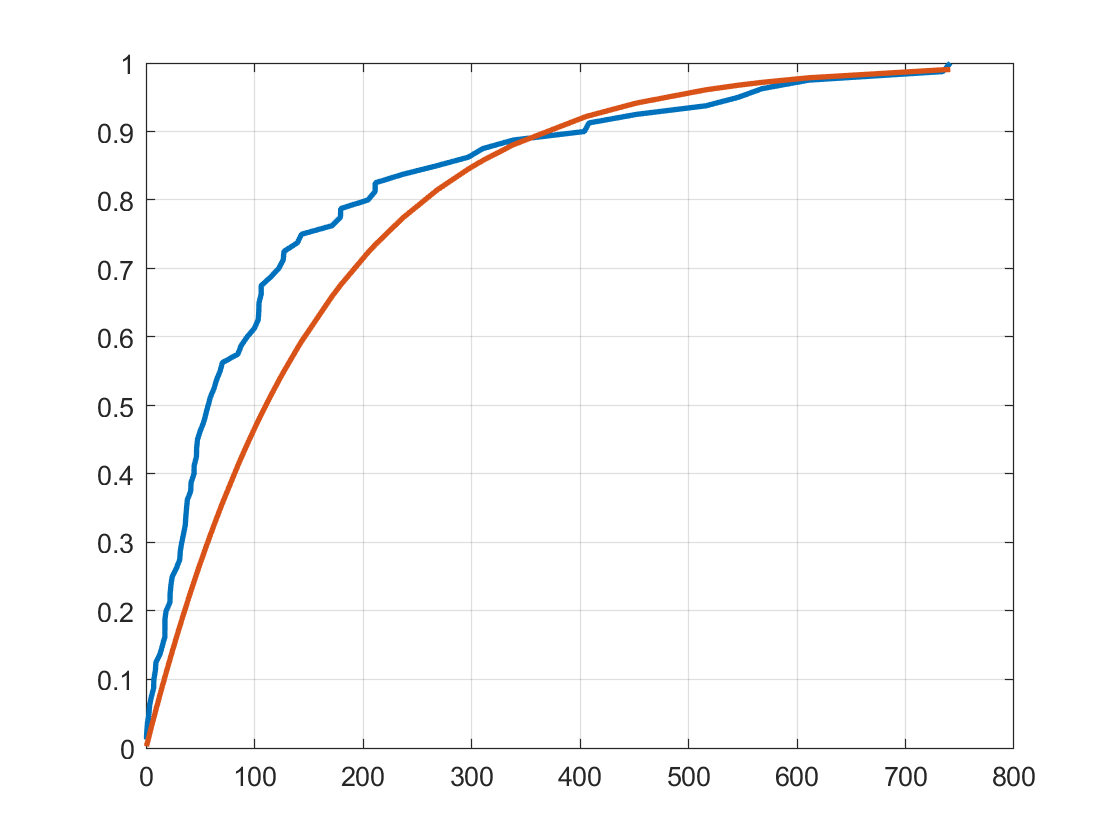

p1_mm = x(1);
l1_mm = x(2);
l2_mm = x(3);

F = @(t) 1 - p1_mm*exp(-l1_mm*t) - (1-p1_mm)*exp(-l2_mm*t);
cdf_data_mm = F(sorted_data);

figure();
plot(sorted_data, t, 'LineWidth', 2);
hold on;
plot(sorted_data, cdf_data_mm, 'LineWidth', 2);
grid on;
hold off;

#### 6.3 Maximum Likelihook & Method of Moments comparison

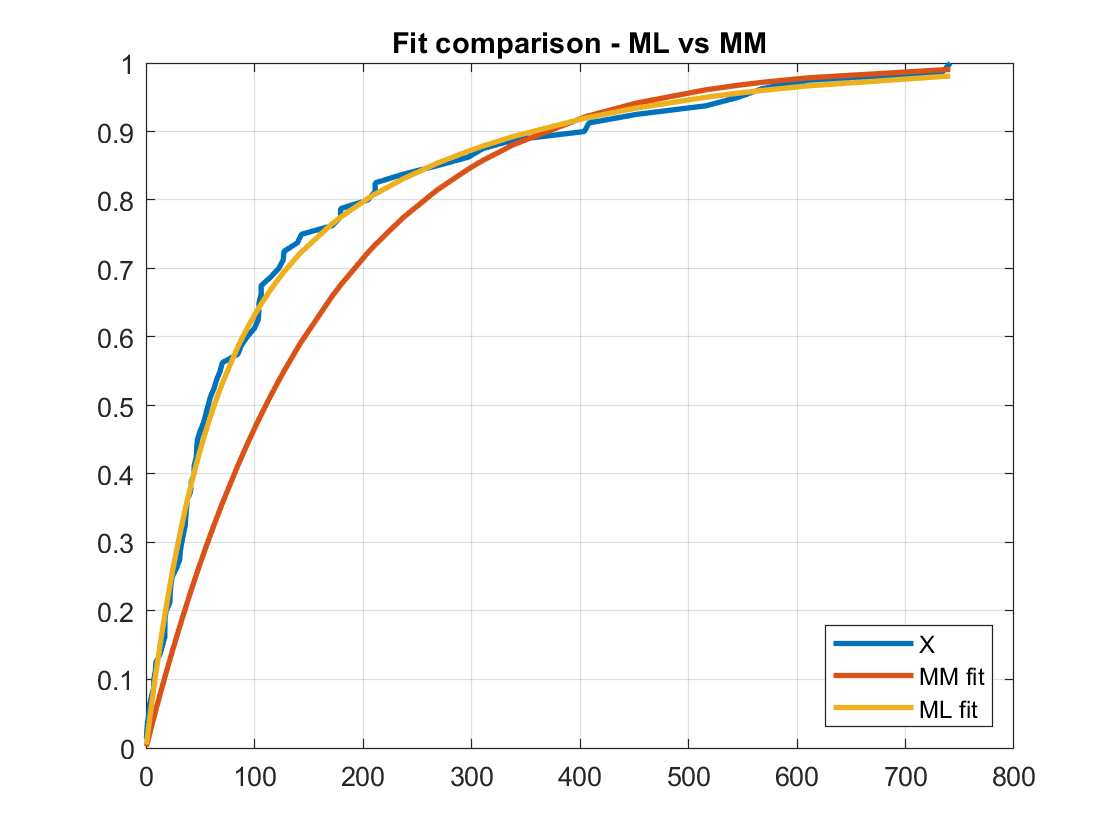

figure();

plot(sorted_data, t, 'LineWidth', 2);
hold on;
plot(sorted_data, cdf_data_mm, 'LineWidth', 2);
hold on;
plot(sorted_data, cdf_data_ml, 'LineWidth', 2);
grid on;
hold off;

legend({'X','MM fit','ML fit'},'Location','southeast');
title('Fit comparison - ML vs MM');